% Read in NetCDF files and output timeseries
clc
clear

## Initializing parameters

% ISMIP6 DATASET
key1_IS = "lithk"; % this should be the variable of interest
key2_IS = "GIS";
key3_IS = "historical";
key4_IS = ".nc";
% unwanted keywords
key_remove_IS = "MUN";
key_remove2_IS = "IMAUICE2";
key_remove3_IS = "PISM";
variable = key1_IS;

% FLOW LINE DATASET
% search keywords
key1_FL = "NW";
key2_FL = "ELA";
key3_FL = ".csv";
% unwanted keyword
key_remove_FL = "Usurf";

% Cartesian coordinates of the data point of interest
data_interest = [-130000, -1985000];

% Number of nearest glacial flow lines we search for
number_of_glacier = 1;
% Number of points sampled per glacial flow line
n_sample = 5; 
% ISMIP dataset (index) used in the visualization
dataset_index = 10;

## Get all interested .nc files

get the path to the uppermost directory for later scanning

original_dir = pwd;
objective_dir = 'ISMIP6 Data and processing';
% trim the path till right before objective_dir
position = strfind(pwd, objective_dir);
starting_path = original_dir(1:position+numel(objective_dir));
% back to where it was originally
cd(original_dir);

% retrieve an ambigous query keyword
keyword = combine_keys(key1_IS, key2_IS, key3_IS, key4_IS);

% query data from files
file_paths = search_files(starting_path, keyword);
file_new_paths = remove_paths(key_remove_IS, file_paths);
file_new_paths = remove_paths(key_remove2_IS, file_new_paths);
file_new_paths = remove_paths(key_remove3_IS, file_new_paths);
ds_all = read_nc_var(file_new_paths, variable);

ans = 'file number 1 is completed'

ans = 'file number 2 is completed'

ans = 'file number 3 is completed'

ans = 'file number 4 is completed'

ans = 'file number 5 is completed'

ans = 'file number 6 is completed'

ans = 'file number 7 is completed'

ans = 'file number 8 is completed'

ans = 'file number 9 is completed'

ans = 'file number 10 is completed'

  ...well there is an error
   successfully meshgrided
   ...Ok polar stereographic proj is given


ans = 'file number 11 is completed'

ans = 'file number 12 is completed'

Corrected the datetime!


ans = 'file number 13 is completed'

Corrected the datetime!


ans = 'file number 14 is completed'

  ...well there is an error
   successfully meshgrided
   ...Ok polar stereographic proj is given


ans = 'file number 15 is completed'

cd(original_dir);

## Get and print a list of experiments and indices

list_table = exp_list(ds_all) 

list_table = 15×2 table
    index            names         
    _____    ______________________

      1      "AWI, ISSM1"          
      2      "AWI, ISSM2"          
      3      "AWI, ISSM3"          
      4      "BGC, BISICLES"       
      5      "GSFC, ISSM"          
      6      "ILTS_PIK, SICOPOLIS1"
      7      "ILTS_PIK, SICOPOLIS2"
      8      "IMAU, IMAUICE1"      
      9      "JPL, ISSM"           
     10      "JPL, ISSMPALEO"      
     11      "LSCE, GRISLI"        
     12      "NCAR, CISM"          
     13      "UCIJPL, ISSM1"       
     14      "UCIJPL, ISSM2"       
     15      "VUB, GISM"           


## Check consistency of model result files

Including if the meshgrids have similar dimensions and similar values (X_a - X_b < tol)

## Animate ISMIP dataset

Here we are visualizing the ice thickness changes

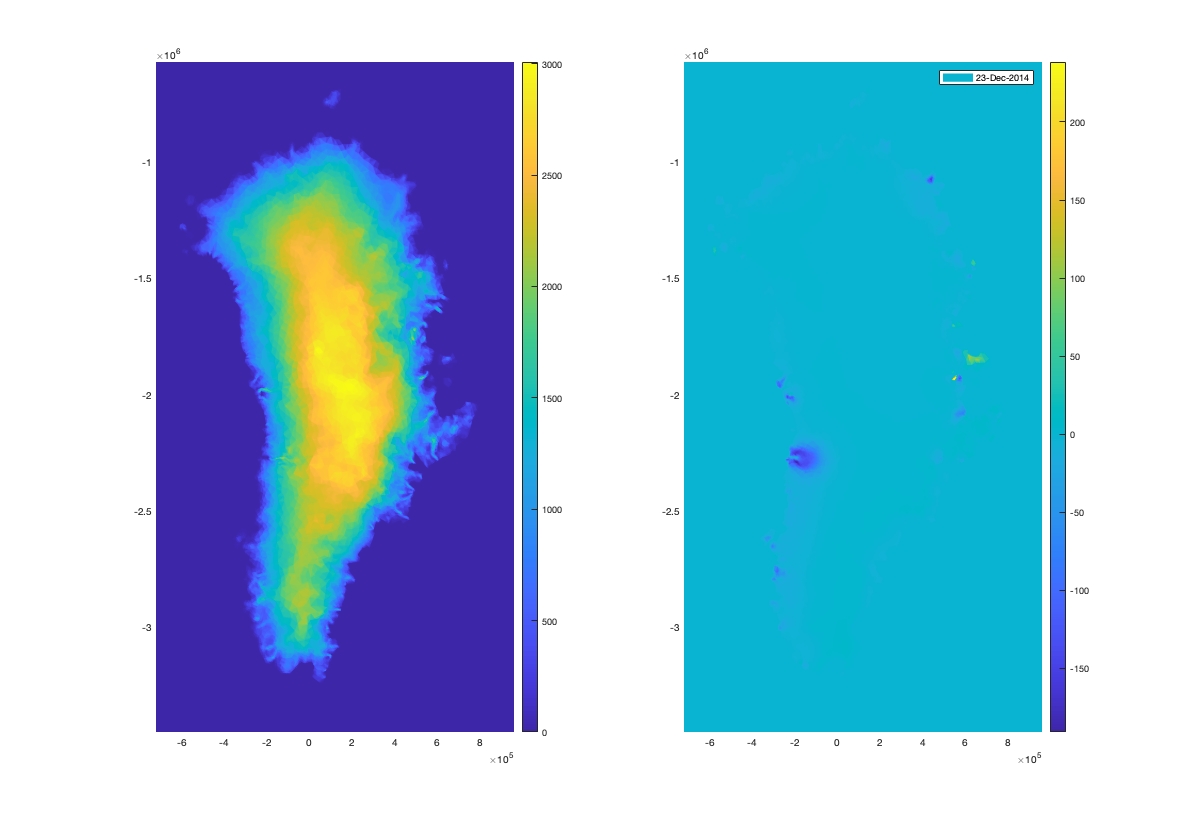

visualize(ds_all, dataset_index)

## Map the mean and standard deviation (at a given year)

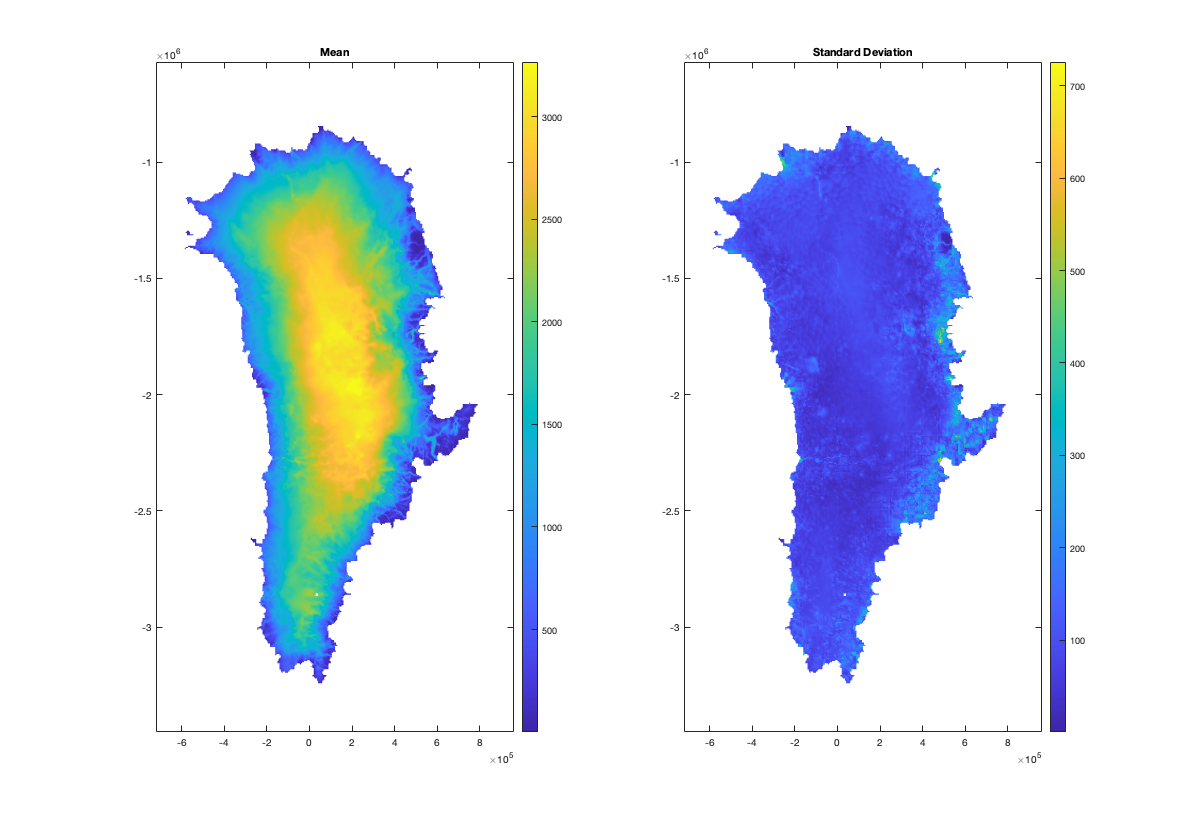

% map the var values at year = 2015/2014
[data_mean, data_std] = map_variance(ds_all, 2015);

## Read in and visualize flow line datasets

The data coordinates are cartesian, hence no need for conversion for demonstration

objective_dir = 'Data and SI';
% trim the path till right before objective_dir
position = strfind(pwd, objective_dir);
starting_path = original_dir(1:position+numel(objective_dir));
folder_name = 'flowlines_kristin/';
starting_path_folderadd = [starting_path, folder_name];

keyword_csv = combine_keys(key1_FL, key2_FL, key3_FL);

% read .csv flowline files
file_paths_csv = search_files(starting_path_folderadd, keyword_csv);
% remove entries with unwanted keyword
file_new_paths_csv = remove_paths(key_remove_FL, file_paths_csv);

% get a cell array containing every flow line data in structures
% data sampling happens here. n_sample is number of points sampled per
% flowline
fl_out = flcsv2struct(file_new_paths_csv, n_sample);

% for a given point (in cartesian), find the nearest five glaciers
% based off the data in fl_out
% data_interest is the point of interest
ng_out = nearest_glaciers(fl_out, data_interest, number_of_glacier);

ans = 'Found No.1 glacier!'

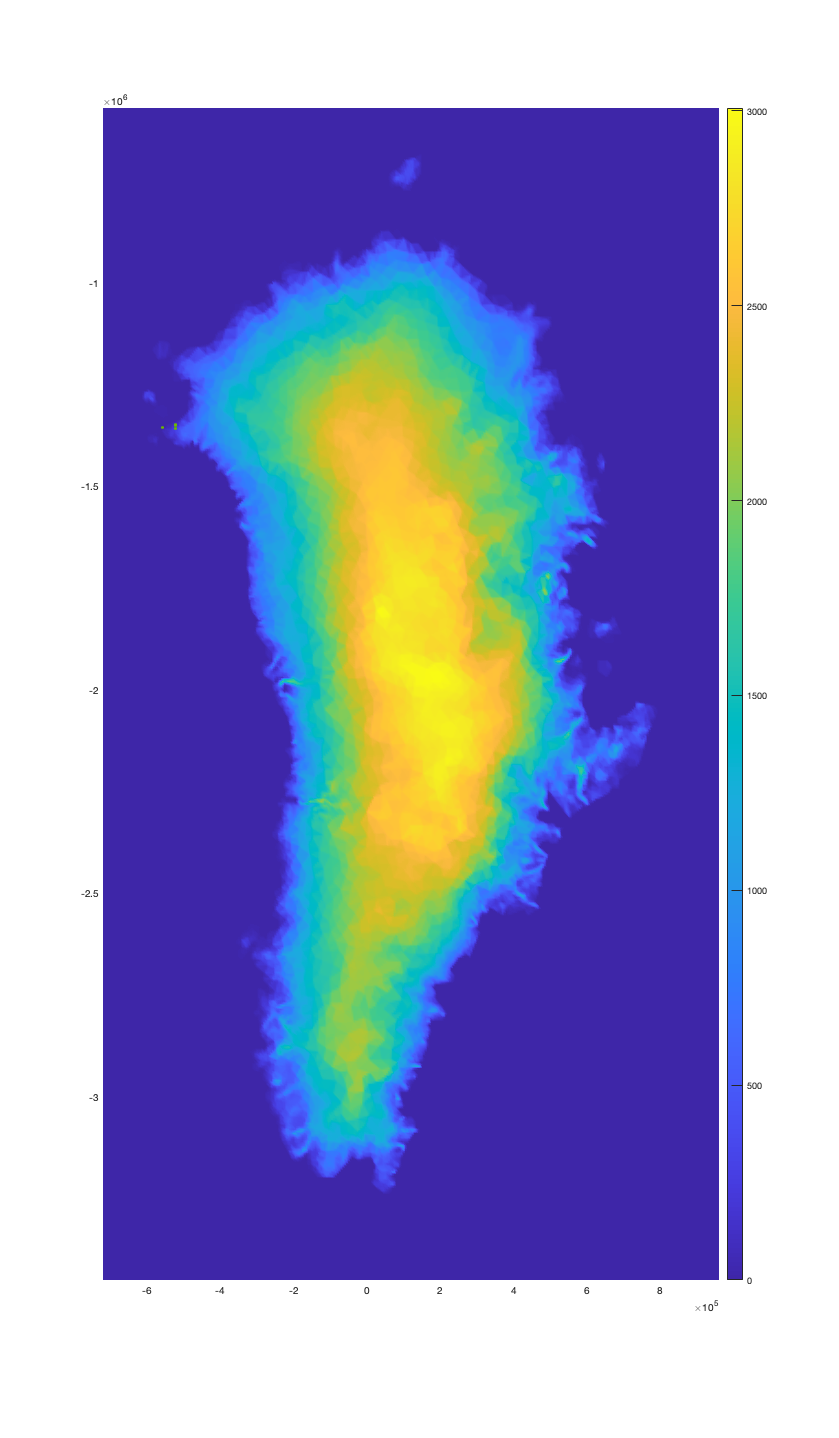


%'VariableNames', {"X", "Y"}
% visualize data points
visualize_flowline(ds_all, ng_out, dataset_index);


cd(original_dir);

## get time series

%glacier_psn = ll2psn(glacier_info_table.Y, glacier_info_table.X);
ts = point2timeseries(ng_out, ds_all, 1);

ans = ' #1 file is completed'

ans = ' #2 file is completed'

ans = ' #3 file is completed'

ans = ' #4 file is completed'

ans = ' #5 file is completed'

ans = ' #6 file is completed'

ans = ' #7 file is completed'

ans = ' #8 file is completed'

ans = ' #9 file is completed'

ans = ' #10 file is completed'

ans = ' #11 file is completed'

ans = ' #12 file is completed'

ans = ' #13 file is completed'

ans = ' #14 file is completed'

ans = ' #15 file is completed'

## visualize

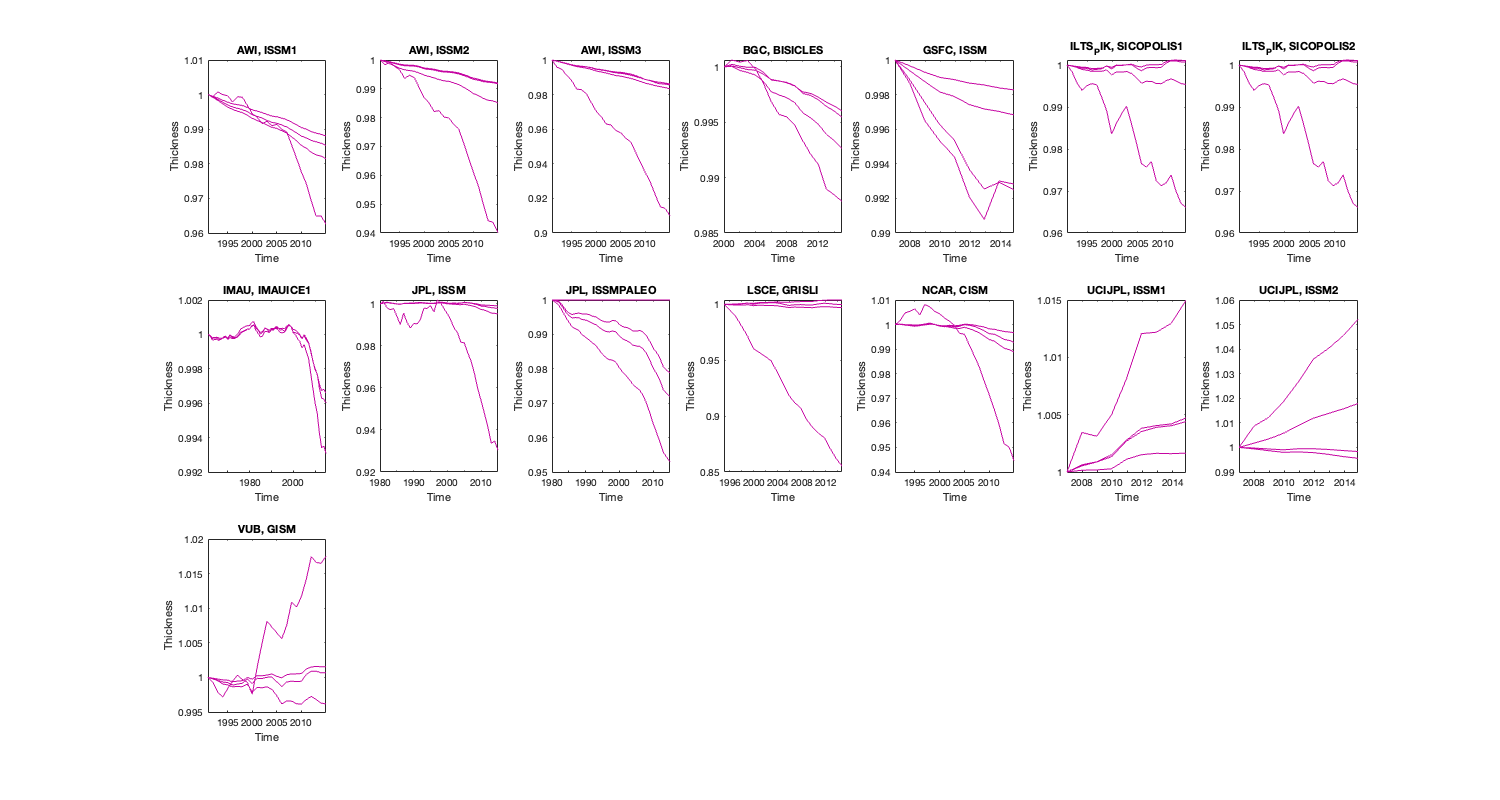

cellarray2plots(ts)

## Visualize the degree of agreement of thinning timeseries among models

% we are only sampling _ point per glacier flow line
n_sample2 = 5;
fl_out = flcsv2struct(file_new_paths_csv, n_sample2);

% make the following plot with the mean thickness we calculated ealier
data_for_plot = data_mean;
thinning_hist_variance(fl_out, ds_all, data_for_plot)

ans = ' #1 file is completed'

ans = ' #2 file is completed'

ans = ' #3 file is completed'

ans = ' #4 file is completed'

ans = ' #5 file is completed'

ans = ' #6 file is completed'

ans = ' #7 file is completed'

ans = ' #8 file is completed'

ans = ' #9 file is completed'

ans = ' #10 file is completed'

ans = ' #11 file is completed'

ans = ' #12 file is completed'

ans = ' #13 file is completed'

ans = ' #14 file is completed'

ans = ' #15 file is completed'

ans = 'Found #1 matrix containing NaN'

ans = 'Found #2 matrix containing NaN'

ans = 'Found #3 matrix containing NaN'

ans = 'Found #4 matrix containing NaN'

ans = 'Found #5 matrix containing NaN'

ans = 'Found #6 matrix containing NaN'

ans = 'Found #7 matrix containing NaN'

ans = 'Found #8 matrix containing NaN'

ans = 'Found #9 matrix containing NaN'

ans = 'Found #10 matrix containing NaN'

ans = 'Found #11 matrix containing NaN'

ans = 'Found #12 matrix containing NaN'

ans = 'Found #13 matrix containing NaN'

ans = 'Found #14 matrix containing NaN'

ans = 'Found #15 matrix containing NaN'

ans = 'Found #16 matrix containing NaN'

ans = 'Found #17 matrix containing NaN'

ans = 'Found #18 matrix containing NaN'

ans = 'Found #19 matrix containing NaN'

ans = 'Found #20 matrix containing NaN'

ans = 'Found #21 matrix containing NaN'

ans = 'Found #22 matrix containing NaN'

ans = 'Found #23 matrix containing NaN'

ans = 'Found #24 matrix containing NaN'

ans = 'Found #25 matrix containing NaN'

ans = 'Found #26 matrix containing NaN'

ans = 'Found #27 matrix containing NaN'

ans = 'Found #28 matrix containing NaN'

ans = 'Found #29 matrix containing NaN'

ans = 'Found #30 matrix containing NaN'

ans = 'Found #31 matrix containing NaN'

ans = 'Found #32 matrix containing NaN'

ans = 'Found #33 matrix containing NaN'

ans = 'Found #34 matrix containing NaN'

ans = 'Found #35 matrix containing NaN'

ans = 'Found #36 matrix containing NaN'

ans = 'Found #37 matrix containing NaN'

ans = 'Found #38 matrix containing NaN'

ans = 'Found #39 matrix containing NaN'

ans = 'Found #40 matrix containing NaN'

ans = 'Found #41 matrix containing NaN'

ans = 'Found #42 matrix containing NaN'

ans = 'Found #43 matrix containing NaN'

ans = 'Found #44 matrix containing NaN'

ans = 'Found #45 matrix containing NaN'

ans = 'Found #46 matrix containing NaN'

ans = 'Found #47 matrix containing NaN'

ans = 'Found #48 matrix containing NaN'

ans = 'Found #49 matrix containing NaN'

ans = 'Found #50 matrix containing NaN'

ans = 'Found #51 matrix containing NaN'

ans = 'Found #52 matrix containing NaN'

ans = 'Found #53 matrix containing NaN'

ans = 'Found #54 matrix containing NaN'

ans = 'Found #55 matrix containing NaN'

ans = 'Found #56 matrix containing NaN'

ans = 'Found #57 matrix containing NaN'

ans = 'Found #58 matrix containing NaN'

ans = 'Found #59 matrix containing NaN'

ans = 'Found #60 matrix containing NaN'

ans = 'Found #61 matrix containing NaN'

ans = 'Found #62 matrix containing NaN'

ans = 'Found #63 matrix containing NaN'

ans = 'Found #64 matrix containing NaN'

ans = 'Found #65 matrix containing NaN'

ans = 'Found #66 matrix containing NaN'

ans = 'Found #67 matrix containing NaN'

ans = 'Found #68 matrix containing NaN'

ans = 'Found #69 matrix containing NaN'

ans = 'Found #70 matrix containing NaN'

ans = 'Found #71 matrix containing NaN'

ans = 'Found #72 matrix containing NaN'

ans = 'Found #73 matrix containing NaN'

ans = 'Found #74 matrix containing NaN'

ans = 'Found #75 matrix containing NaN'

ans = 'Found #76 matrix containing NaN'

ans = 'Found #77 matrix containing NaN'

ans = 'Found #78 matrix containing NaN'

ans = 'Found #79 matrix containing NaN'

ans = 'Found #80 matrix containing NaN'

ans = 'Found #81 matrix containing NaN'

ans = 'Found #82 matrix containing NaN'

ans = 'Found #83 matrix containing NaN'

ans = 'Found #84 matrix containing NaN'

ans = 'Found #85 matrix containing NaN'

ans = 'Found #86 matrix containing NaN'

ans = 'Found #87 matrix containing NaN'

ans = 'Found #88 matrix containing NaN'

ans = 'Found #89 matrix containing NaN'

ans = 'Found #90 matrix containing NaN'

ans = 'Found #91 matrix containing NaN'

ans = 'Found #92 matrix containing NaN'

ans = 'Found #93 matrix containing NaN'

ans = 'Found #94 matrix containing NaN'

ans = 'Found #95 matrix containing NaN'

ans = 'Found #96 matrix containing NaN'

ans = 'Found #97 matrix containing NaN'

ans = 'Found #98 matrix containing NaN'

ans = 'Found #99 matrix containing NaN'

ans = 'Found #100 matrix containing NaN'

ans = 'Found #101 matrix containing NaN'

ans = 'Found #102 matrix containing NaN'

ans = 'Found #103 matrix containing NaN'

ans = 'Found #104 matrix containing NaN'

ans = 'Found #105 matrix containing NaN'

ans = 'Found #106 matrix containing NaN'

ans = 'Found #107 matrix containing NaN'

ans = 'Found #108 matrix containing NaN'

ans = 'Found #109 matrix containing NaN'

ans = 'Found #110 matrix containing NaN'

ans = 'Found #111 matrix containing NaN'

ans = 'Found #112 matrix containing NaN'

ans = 'Found #113 matrix containing NaN'

ans = 'Found #114 matrix containing NaN'

ans = 'Found #115 matrix containing NaN'

ans = 'Found #116 matrix containing NaN'

ans = 'Found #117 matrix containing NaN'

ans = 'Found #118 matrix containing NaN'

ans = 'Found #119 matrix containing NaN'

ans = 'Found #120 matrix containing NaN'

ans = 'Found #121 matrix containing NaN'

ans = 'Found #122 matrix containing NaN'

ans = 'Found #123 matrix containing NaN'

ans = 'Found #124 matrix containing NaN'

ans = 'Found #125 matrix containing NaN'

ans = 'Found #126 matrix containing NaN'

ans = 'Found #127 matrix containing NaN'

ans = 'Found #128 matrix containing NaN'

ans = 'Found #129 matrix containing NaN'

ans = 'Found #130 matrix containing NaN'

ans = 'Found #131 matrix containing NaN'

ans = 'Found #132 matrix containing NaN'

ans = 'Found #133 matrix containing NaN'

ans = 'Found #134 matrix containing NaN'

ans = 'Found #135 matrix containing NaN'

ans = 'Found #136 matrix containing NaN'

ans = 'Found #137 matrix containing NaN'

ans = 'Found #138 matrix containing NaN'

ans = 'Found #139 matrix containing NaN'

ans = 'Found #140 matrix containing NaN'

ans = 'Found #141 matrix containing NaN'

ans = 'Found #142 matrix containing NaN'

ans = 'Found #143 matrix containing NaN'

ans = 'Found #144 matrix containing NaN'

ans = 'Found #145 matrix containing NaN'

ans = 'Found #146 matrix containing NaN'

ans = 'Found #147 matrix containing NaN'

ans = 'Found #148 matrix containing NaN'

ans = 'Found #149 matrix containing NaN'

ans = 'Found #150 matrix containing NaN'

ans = 'Found #151 matrix containing NaN'

ans = 'Found #152 matrix containing NaN'

ans = 'Found #153 matrix containing NaN'

ans = 'Found #154 matrix containing NaN'

ans = 'Found #155 matrix containing NaN'

ans = 'Found #156 matrix containing NaN'

ans = 'Found #157 matrix containing NaN'

ans = 'Found #158 matrix containing NaN'

ans = 'Found #159 matrix containing NaN'

ans = 'Found #160 matrix containing NaN'

ans = 'Found #161 matrix containing NaN'

ans = 'Found #162 matrix containing NaN'

ans = 'Found #163 matrix containing NaN'

ans = 'Found #164 matrix containing NaN'

ans = 'Found #165 matrix containing NaN'

ans = 'Found #166 matrix containing NaN'

ans = 'Found #167 matrix containing NaN'

ans = 'Found #168 matrix containing NaN'

ans = 'Found #169 matrix containing NaN'

ans = 'Found #170 matrix containing NaN'

ans = 'Found #171 matrix containing NaN'

ans = 'Found #172 matrix containing NaN'

ans = 'Found #173 matrix containing NaN'

ans = 'Found #174 matrix containing NaN'

ans = 'Found #175 matrix containing NaN'

ans = 'Found #176 matrix containing NaN'

ans = 'Found #177 matrix containing NaN'

ans = 'Found #178 matrix containing NaN'

ans = 'Found #179 matrix containing NaN'

ans = 'Found #180 matrix containing NaN'

ans = 'Found #181 matrix containing NaN'

ans = 'Found #182 matrix containing NaN'

ans = 'Found #183 matrix containing NaN'

ans = 'Found #184 matrix containing NaN'

ans = 'Found #185 matrix containing NaN'

ans = 'Found #186 matrix containing NaN'

ans = 'Found #187 matrix containing NaN'

ans = 'Found #188 matrix containing NaN'

ans = 'Found #189 matrix containing NaN'

ans = 'Found #190 matrix containing NaN'

ans = 'Found #191 matrix containing NaN'

ans = 'Found #192 matrix containing NaN'

ans = 'Found #193 matrix containing NaN'

ans = 'Found #194 matrix containing NaN'

ans = 'Found #195 matrix containing NaN'

ans = 'Found #196 matrix containing NaN'

ans = 'Found #197 matrix containing NaN'

ans = 'Found #198 matrix containing NaN'

ans = 'Found #199 matrix containing NaN'

ans = 'Found #200 matrix containing NaN'

ans = 'Found #201 matrix containing NaN'

ans = 'Found #202 matrix containing NaN'

ans = 'Found #203 matrix containing NaN'

ans = 'Found #204 matrix containing NaN'

ans = 'Found #205 matrix containing NaN'

ans = 'Found #206 matrix containing NaN'

ans = 'Found #207 matrix containing NaN'

ans = 'Found #208 matrix containing NaN'

ans = 'Found #209 matrix containing NaN'

ans = 'Found #210 matrix containing NaN'

ans = 'Found #211 matrix containing NaN'

ans = 'Found #212 matrix containing NaN'

ans = 'Found #213 matrix containing NaN'

ans = 'Found #214 matrix containing NaN'

ans = 'Found #215 matrix containing NaN'

ans = 'Found #216 matrix containing NaN'

ans = 'Found #217 matrix containing NaN'

ans = 'Found #218 matrix containing NaN'

ans = 'Found #219 matrix containing NaN'

ans = 'Found #220 matrix containing NaN'

ans = 'Found #221 matrix containing NaN'

ans = 'Found #222 matrix containing NaN'

ans = 'Found #223 matrix containing NaN'

ans = 'Found #224 matrix containing NaN'

ans = 'Found #225 matrix containing NaN'

ans = 'Found #226 matrix containing NaN'

ans = 'Found #227 matrix containing NaN'

ans = 'Found #228 matrix containing NaN'

ans = 'Found #229 matrix containing NaN'

ans = 'Found #230 matrix containing NaN'

ans = 'Found #231 matrix containing NaN'

ans = 'Found #232 matrix containing NaN'

ans = 'Found #233 matrix containing NaN'

ans = 'Found #234 matrix containing NaN'

ans = 'Found #235 matrix containing NaN'

ans = 'Found #236 matrix containing NaN'

ans = 'Found #237 matrix containing NaN'

ans = 'Found #238 matrix containing NaN'

ans = 'Found #239 matrix containing NaN'

ans = 'Found #240 matrix containing NaN'

ans = 'Found #241 matrix containing NaN'

ans = 'Found #242 matrix containing NaN'

ans = 'Found #243 matrix containing NaN'

ans = 'Found #244 matrix containing NaN'

ans = 'Found #245 matrix containing NaN'

ans = 'Found #246 matrix containing NaN'

ans = 'Found #247 matrix containing NaN'

ans = 'Found #248 matrix containing NaN'

ans = 'Found #249 matrix containing NaN'

ans = 'Found #250 matrix containing NaN'

ans = 'Found #251 matrix containing NaN'

ans = 'Found #252 matrix containing NaN'

ans = 'Found #253 matrix containing NaN'

ans = 'Found #254 matrix containing NaN'

ans = 'Found #255 matrix containing NaN'

ans = 'Found #256 matrix containing NaN'

ans = 'Found #257 matrix containing NaN'

ans = 'Found #258 matrix containing NaN'

ans = 'Found #259 matrix containing NaN'

ans = 'Found #260 matrix containing NaN'

ans = 'Found #261 matrix containing NaN'

ans = 'Found #262 matrix containing NaN'

ans = 'Found #263 matrix containing NaN'

ans = 'Found #264 matrix containing NaN'

ans = 'Found #265 matrix containing NaN'

ans = 'Found #266 matrix containing NaN'

ans = 'Found #267 matrix containing NaN'

ans = 'Found #268 matrix containing NaN'

ans = 'Found #269 matrix containing NaN'

ans = 'Found #270 matrix containing NaN'

ans = 'Found #271 matrix containing NaN'

ans = 'Found #272 matrix containing NaN'

ans = 'Found #273 matrix containing NaN'

ans = 'Found #274 matrix containing NaN'

ans = 'Found #275 matrix containing NaN'

ans = 'Found #276 matrix containing NaN'

ans = 'Found #277 matrix containing NaN'

ans = 'Found #278 matrix containing NaN'

ans = 'Found #279 matrix containing NaN'

ans = 'Found #280 matrix containing NaN'

ans = 'Found #281 matrix containing NaN'

ans = 'Found #282 matrix containing NaN'

ans = 'Found #283 matrix containing NaN'

ans = 'Found #284 matrix containing NaN'

ans = 'Found #285 matrix containing NaN'

ans = 'Found #286 matrix containing NaN'

ans = 'Found #287 matrix containing NaN'

ans = 'Found #288 matrix containing NaN'

ans = 'Found #289 matrix containing NaN'

ans = 'Found #290 matrix containing NaN'

ans = 'Found #291 matrix containing NaN'

ans = 'Found #292 matrix containing NaN'

ans = 'Found #293 matrix containing NaN'

ans = 'Found #294 matrix containing NaN'

ans = 'Found #295 matrix containing NaN'

ans = 'Found #296 matrix containing NaN'

ans = 'Found #297 matrix containing NaN'

ans = 'Found #298 matrix containing NaN'

ans = 'Found #299 matrix containing NaN'

ans = 'Found #300 matrix containing NaN'

ans = 'Found #301 matrix containing NaN'

ans = 'Found #302 matrix containing NaN'

ans = 'Found #303 matrix containing NaN'

ans = 'Found #304 matrix containing NaN'

ans = 'Found #305 matrix containing NaN'

ans = 'Found #306 matrix containing NaN'

ans = 'Found #307 matrix containing NaN'

ans = 'Found #308 matrix containing NaN'

ans = 'Found #309 matrix containing NaN'

ans = 'Found #310 matrix containing NaN'

ans = 'Found #311 matrix containing NaN'

ans = 'Found #312 matrix containing NaN'

ans = 'Found #313 matrix containing NaN'

ans = 'Found #314 matrix containing NaN'

ans = 'Found #315 matrix containing NaN'

ans = 'Found #316 matrix containing NaN'

ans = 'Found #317 matrix containing NaN'

ans = 'Found #318 matrix containing NaN'

ans = 'Found #319 matrix containing NaN'

ans = 'Found #320 matrix containing NaN'

ans = 'Found #321 matrix containing NaN'

ans = 'Found #322 matrix containing NaN'

ans = 'Found #323 matrix containing NaN'

ans = 'Found #324 matrix containing NaN'

ans = 'Found #325 matrix containing NaN'

ans = 'Found #326 matrix containing NaN'

ans = 'Found #327 matrix containing NaN'

ans = 'Found #328 matrix containing NaN'

ans = 'Found #329 matrix containing NaN'

ans = 'Found #330 matrix containing NaN'

ans = 'Found #331 matrix containing NaN'

ans = 'Found #332 matrix containing NaN'

ans = 'Found #333 matrix containing NaN'

ans = 'Found #334 matrix containing NaN'

ans = 'Found #335 matrix containing NaN'

ans = 'Found #336 matrix containing NaN'

ans = 'Found #337 matrix containing NaN'

ans = 'Found #338 matrix containing NaN'

ans = 'Found #339 matrix containing NaN'

ans = 'Found #340 matrix containing NaN'

ans = 'Found #341 matrix containing NaN'

ans = 'Found #342 matrix containing NaN'

ans = 'Found #343 matrix containing NaN'

ans = 'Found #344 matrix containing NaN'

ans = 'Found #345 matrix containing NaN'

ans = 'Found #346 matrix containing NaN'

ans = 'Found #347 matrix containing NaN'

ans = 'Found #348 matrix containing NaN'

ans = 'Found #349 matrix containing NaN'

ans = 'Found #350 matrix containing NaN'

ans = 'Found #351 matrix containing NaN'

ans = 'Found #352 matrix containing NaN'

ans = 'Found #353 matrix containing NaN'

ans = 'Found #354 matrix containing NaN'

ans = 'Found #355 matrix containing NaN'

ans = 'Found #356 matrix containing NaN'

ans = 'Found #357 matrix containing NaN'

ans = 'Found #358 matrix containing NaN'

ans = 'Found #359 matrix containing NaN'

ans = 'Found #360 matrix containing NaN'

ans = 'Found #361 matrix containing NaN'

ans = 'Found #362 matrix containing NaN'

ans = 'Found #363 matrix containing NaN'

ans = 'Found #364 matrix containing NaN'

ans = 'Found #365 matrix containing NaN'

ans = 'Found #366 matrix containing NaN'

ans = 'Found #367 matrix containing NaN'

ans = 'Found #368 matrix containing NaN'

ans = 'Found #369 matrix containing NaN'

ans = 'Found #370 matrix containing NaN'

ans = 'Found #371 matrix containing NaN'

ans = 'Found #372 matrix containing NaN'

ans = 'Found #373 matrix containing NaN'

ans = 'Found #374 matrix containing NaN'

ans = 'Found #375 matrix containing NaN'

ans = 'Found #376 matrix containing NaN'

ans = 'Found #377 matrix containing NaN'

ans = 'Found #378 matrix containing NaN'

ans = 'Found #379 matrix containing NaN'

ans = 'Found #380 matrix containing NaN'

ans = 'Found #381 matrix containing NaN'

ans = 'Found #382 matrix containing NaN'

ans = 'Found #383 matrix containing NaN'

ans = 'Found #384 matrix containing NaN'

ans = 'Found #385 matrix containing NaN'

ans = 'Found #386 matrix containing NaN'

ans = 'Found #387 matrix containing NaN'

ans = 'Found #388 matrix containing NaN'

ans = 'Found #389 matrix containing NaN'

ans = 'Found #390 matrix containing NaN'

ans = 'Found #391 matrix containing NaN'

ans = 'Found #392 matrix containing NaN'

ans = 'Found #393 matrix containing NaN'

ans = 'Found #394 matrix containing NaN'

ans = 'Found #395 matrix containing NaN'

ans = 'Found #396 matrix containing NaN'

ans = 'Found #397 matrix containing NaN'

ans = 'Found #398 matrix containing NaN'

ans = 'Found #399 matrix containing NaN'

ans = 'Found #400 matrix containing NaN'

ans = 'Found #401 matrix containing NaN'

ans = 'Found #402 matrix containing NaN'

ans = 'Found #403 matrix containing NaN'

ans = 'Found #404 matrix containing NaN'

ans = 'Found #405 matrix containing NaN'

ans = 'Found #406 matrix containing NaN'

ans = 'Found #407 matrix containing NaN'

ans = 'Found #408 matrix containing NaN'

ans = 'Found #409 matrix containing NaN'

ans = 'Found #410 matrix containing NaN'

ans = 'Found #411 matrix containing NaN'

ans = 'Found #412 matrix containing NaN'

ans = 'Found #413 matrix containing NaN'

ans = 'Found #414 matrix containing NaN'

ans = 'Found #415 matrix containing NaN'

ans = 'Found #416 matrix containing NaN'

ans = 'Found #417 matrix containing NaN'

ans = 'Found #418 matrix containing NaN'

ans = 'Found #419 matrix containing NaN'

ans = 'Found #420 matrix containing NaN'

ans = 'Found #421 matrix containing NaN'

ans = 'Found #422 matrix containing NaN'

ans = 'Found #423 matrix containing NaN'

ans = 'Found #424 matrix containing NaN'

ans = 'Found #425 matrix containing NaN'

ans = 'Found #426 matrix containing NaN'

ans = 'Found #427 matrix containing NaN'

ans = 'Found #428 matrix containing NaN'

ans = 'Found #429 matrix containing NaN'

ans = 'Found #430 matrix containing NaN'

ans = 'Found #431 matrix containing NaN'

ans = 'Found #432 matrix containing NaN'

ans = 'Found #433 matrix containing NaN'

ans = 'Found #434 matrix containing NaN'

ans = 'Found #435 matrix containing NaN'

ans = 'Found #436 matrix containing NaN'

ans = 'Found #437 matrix containing NaN'

ans = 'Found #438 matrix containing NaN'

ans = 'Found #439 matrix containing NaN'

ans = 'Found #440 matrix containing NaN'

ans = 'Found #441 matrix containing NaN'

ans = 'Found #442 matrix containing NaN'

ans = 'Found #443 matrix containing NaN'

ans = 'Found #444 matrix containing NaN'

ans = 'Found #445 matrix containing NaN'

ans = 'Found #446 matrix containing NaN'

ans = 'Found #447 matrix containing NaN'

ans = 'Found #448 matrix containing NaN'

ans = 'Found #449 matrix containing NaN'

ans = 'Found #450 matrix containing NaN'

ans = 'Found #451 matrix containing NaN'

ans = 'Found #452 matrix containing NaN'

ans = 'Found #453 matrix containing NaN'

ans = 'Found #454 matrix containing NaN'

ans = 'Found #455 matrix containing NaN'

ans = 'Found #456 matrix containing NaN'

ans = 'Found #457 matrix containing NaN'

ans = 'Found #458 matrix containing NaN'

ans = 'Found #459 matrix containing NaN'

ans = 'Found #460 matrix containing NaN'

ans = 'Found #461 matrix containing NaN'

ans = 'Found #462 matrix containing NaN'

ans = 'Found #463 matrix containing NaN'

ans = 'Found #464 matrix containing NaN'

ans = 'Found #465 matrix containing NaN'

ans = 'Found #466 matrix containing NaN'

ans = 'Found #467 matrix containing NaN'

ans = 'Found #468 matrix containing NaN'

ans = 'Found #469 matrix containing NaN'

ans = 'Found #470 matrix containing NaN'

ans = 'Found #471 matrix containing NaN'

ans = 'Found #472 matrix containing NaN'

ans = 'Found #473 matrix containing NaN'

ans = 'Found #474 matrix containing NaN'

ans = 'Found #475 matrix containing NaN'

ans = 'Found #476 matrix containing NaN'

ans = 'Found #477 matrix containing NaN'

ans = 'Found #478 matrix containing NaN'

ans = 'Found #479 matrix containing NaN'

ans = 'Found #480 matrix containing NaN'

ans = 'Found #481 matrix containing NaN'

ans = 'Found #482 matrix containing NaN'

ans = 'Found #483 matrix containing NaN'

ans = 'Found #484 matrix containing NaN'

ans = 'Found #485 matrix containing NaN'

ans = 'Found #486 matrix containing NaN'

ans = 'Found #487 matrix containing NaN'

ans = 'Found #488 matrix containing NaN'

ans = 'Found #489 matrix containing NaN'

ans = 'Found #490 matrix containing NaN'

ans = 'Found #491 matrix containing NaN'

ans = 'Found #492 matrix containing NaN'

ans = 'Found #493 matrix containing NaN'

ans = 'Found #494 matrix containing NaN'

ans = 'Found #495 matrix containing NaN'

ans = 'Found #496 matrix containing NaN'

ans = 'Found #497 matrix containing NaN'

ans = 'Found #498 matrix containing NaN'

ans = 'Found #499 matrix containing NaN'

ans = 'Found #500 matrix containing NaN'

ans = 'Found #501 matrix containing NaN'

ans = 'Found #502 matrix containing NaN'

ans = 'Found #503 matrix containing NaN'

ans = 'Found #504 matrix containing NaN'

ans = 'Found #505 matrix containing NaN'

ans = 'Found #506 matrix containing NaN'

ans = 'Found #507 matrix containing NaN'

ans = 'Found #508 matrix containing NaN'

ans = 'Found #509 matrix containing NaN'

ans = 'Found #510 matrix containing NaN'

ans = 'Found #511 matrix containing NaN'

ans = 'Found #512 matrix containing NaN'

ans = 'Found #513 matrix containing NaN'

ans = 'Found #514 matrix containing NaN'

ans = 'Found #515 matrix containing NaN'

ans = 'Found #516 matrix containing NaN'

ans = 'Found #517 matrix containing NaN'

ans = 'Found #518 matrix containing NaN'

ans = 'Found #519 matrix containing NaN'

ans = 'Found #520 matrix containing NaN'

ans = 'Found #521 matrix containing NaN'

ans = 'Found #522 matrix containing NaN'

ans = 'Found #523 matrix containing NaN'

ans = 'Found #524 matrix containing NaN'

ans = 'Found #525 matrix containing NaN'

ans = 'Found #526 matrix containing NaN'

ans = 'Found #527 matrix containing NaN'

ans = 'Found #528 matrix containing NaN'

ans = 'Found #529 matrix containing NaN'

ans = 'Found #530 matrix containing NaN'

ans = 'Found #531 matrix containing NaN'

ans = 'Found #532 matrix containing NaN'

ans = 'Found #533 matrix containing NaN'

ans = 'Found #534 matrix containing NaN'

ans = 'Found #535 matrix containing NaN'

ans = 'Found #536 matrix containing NaN'

ans = 'Found #537 matrix containing NaN'

ans = 'Found #538 matrix containing NaN'

ans = 'Found #539 matrix containing NaN'

ans = 'Found #540 matrix containing NaN'

ans = 'Found #541 matrix containing NaN'

ans = 'Found #542 matrix containing NaN'

ans = 'Found #543 matrix containing NaN'

ans = 'Found #544 matrix containing NaN'

ans = 'Found #545 matrix containing NaN'

ans = 'Found #546 matrix containing NaN'

ans = 'Found #547 matrix containing NaN'

ans = 'Found #548 matrix containing NaN'

ans = 'Found #549 matrix containing NaN'

ans = 'Found #550 matrix containing NaN'

ans = 'Found #551 matrix containing NaN'

ans = 'Found #552 matrix containing NaN'

ans = 'Found #553 matrix containing NaN'

ans = 'Found #554 matrix containing NaN'

ans = 'Found #555 matrix containing NaN'

ans = 'Found #556 matrix containing NaN'

ans = 'Found #557 matrix containing NaN'

ans = 'Found #558 matrix containing NaN'

ans = 'Found #559 matrix containing NaN'

ans = 'Found #560 matrix containing NaN'

ans = 'Found #561 matrix containing NaN'

ans = 'Found #562 matrix containing NaN'

ans = 'Found #563 matrix containing NaN'

ans = 'Found #564 matrix containing NaN'

ans = 'Found #565 matrix containing NaN'

ans = 'Found #566 matrix containing NaN'

ans = 'Found #567 matrix containing NaN'

ans = 'Found #568 matrix containing NaN'

ans = 'Found #569 matrix containing NaN'

ans = 'Found #570 matrix containing NaN'

ans = 'Found #571 matrix containing NaN'

ans = 'Found #572 matrix containing NaN'

ans = 'Found #573 matrix containing NaN'

ans = 'Found #574 matrix containing NaN'

ans = 'Found #575 matrix containing NaN'

ans = 'Found #576 matrix containing NaN'

ans = 'Found #577 matrix containing NaN'

ans = 'Found #578 matrix containing NaN'

ans = 'Found #579 matrix containing NaN'

ans = 'Found #580 matrix containing NaN'

ans = 'Found #581 matrix containing NaN'

ans = 'Found #582 matrix containing NaN'

ans = 'Found #583 matrix containing NaN'

ans = 'Found #584 matrix containing NaN'

ans = 'Found #585 matrix containing NaN'

ans = 'Found #586 matrix containing NaN'

ans = 'Found #587 matrix containing NaN'

ans = 'Found #588 matrix containing NaN'

ans = 'Found #589 matrix containing NaN'

ans = 'Found #590 matrix containing NaN'

ans = 'Found #591 matrix containing NaN'

ans = 'Found #592 matrix containing NaN'

ans = 'Found #593 matrix containing NaN'

ans = 'Found #594 matrix containing NaN'

ans = 'Found #595 matrix containing NaN'

ans = 'Found #596 matrix containing NaN'

ans = 'Found #597 matrix containing NaN'

ans = 'Found #598 matrix containing NaN'

ans = 'Found #599 matrix containing NaN'

ans = 'Found #600 matrix containing NaN'

ans = 'Found #601 matrix containing NaN'

ans = 'Found #602 matrix containing NaN'

ans = 'Found #603 matrix containing NaN'

ans = 'Found #604 matrix containing NaN'

ans = 'Found #605 matrix containing NaN'

ans = 'Found #606 matrix containing NaN'

ans = 'Found #607 matrix containing NaN'

ans = 'Found #608 matrix containing NaN'

ans = 'Found #609 matrix containing NaN'

ans = 'Found #610 matrix containing NaN'

ans = 'Found #611 matrix containing NaN'

ans = 'Found #612 matrix containing NaN'

ans = 'Found #613 matrix containing NaN'

ans = 'Found #614 matrix containing NaN'

ans = 'Found #615 matrix containing NaN'

ans = 'Found #616 matrix containing NaN'

ans = 'Found #617 matrix containing NaN'

ans = 'Found #618 matrix containing NaN'

ans = 'Found #619 matrix containing NaN'

ans = 'Found #620 matrix containing NaN'

ans = 'Found #621 matrix containing NaN'

ans = 'Found #622 matrix containing NaN'

ans = 'Found #623 matrix containing NaN'

ans = 'Found #624 matrix containing NaN'

ans = 'Found #625 matrix containing NaN'

ans = 'Found #626 matrix containing NaN'

ans = 'Found #627 matrix containing NaN'

ans = 'Found #628 matrix containing NaN'

ans = 'Found #629 matrix containing NaN'

ans = 'Found #630 matrix containing NaN'

ans = 'Found #631 matrix containing NaN'

ans = 'Found #632 matrix containing NaN'

ans = 'Found #633 matrix containing NaN'

ans = 'Found #634 matrix containing NaN'

ans = 'Found #635 matrix containing NaN'

ans = 'Found #636 matrix containing NaN'

ans = 'Found #637 matrix containing NaN'

ans = 'Found #638 matrix containing NaN'

ans = 'Found #639 matrix containing NaN'

ans = 'Found #640 matrix containing NaN'

ans = 'Found #641 matrix containing NaN'

ans = 'Found #642 matrix containing NaN'

ans = 'Found #643 matrix containing NaN'

ans = 'Found #644 matrix containing NaN'

ans = 'Found #645 matrix containing NaN'

ans = 'Found #646 matrix containing NaN'

ans = 'Found #647 matrix containing NaN'

ans = 'Found #648 matrix containing NaN'

ans = 'Found #649 matrix containing NaN'

ans = 'Found #650 matrix containing NaN'

ans = 'Found #651 matrix containing NaN'

ans = 'Found #652 matrix containing NaN'

ans = 'Found #653 matrix containing NaN'

ans = 'Found #654 matrix containing NaN'

ans = 'Found #655 matrix containing NaN'

ans = 'Found #656 matrix containing NaN'

ans = 'Found #657 matrix containing NaN'

ans = 'Found #658 matrix containing NaN'

ans = 'Found #659 matrix containing NaN'

ans = 'Found #660 matrix containing NaN'

ans = 'Found #661 matrix containing NaN'

ans = 'Found #662 matrix containing NaN'

ans = 'Found #663 matrix containing NaN'

ans = 'Found #664 matrix containing NaN'

ans = 'Found #665 matrix containing NaN'

ans = 'Found #666 matrix containing NaN'

ans = 'Found #667 matrix containing NaN'

ans = 'Found #668 matrix containing NaN'

ans = 'Found #669 matrix containing NaN'

ans = 'Found #670 matrix containing NaN'

ans = 'Found #671 matrix containing NaN'

ans = 'Found #672 matrix containing NaN'

ans = 'Found #673 matrix containing NaN'

ans = 'Found #674 matrix containing NaN'

ans = 'Found #675 matrix containing NaN'

ans = 'Found #676 matrix containing NaN'

ans = 'Found #677 matrix containing NaN'

ans = 'Found #678 matrix containing NaN'

ans = 'Found #679 matrix containing NaN'

ans = 'Found #680 matrix containing NaN'

ans = 'Found #681 matrix containing NaN'

ans = 'Found #682 matrix containing NaN'

ans = 'Found #683 matrix containing NaN'

ans = 'Found #684 matrix containing NaN'

ans = 'Found #685 matrix containing NaN'

ans = 'Found #686 matrix containing NaN'

ans = 'Found #687 matrix containing NaN'

ans = 'Found #688 matrix containing NaN'

ans = 'Found #689 matrix containing NaN'

ans = 'Found #690 matrix containing NaN'

ans = 'Found #691 matrix containing NaN'

ans = 'Found #692 matrix containing NaN'

ans = 'Found #693 matrix containing NaN'

ans = 'Found #694 matrix containing NaN'

ans = 'Found #695 matrix containing NaN'

ans = 'Found #696 matrix containing NaN'

ans = 'Found #697 matrix containing NaN'

ans = 'Found #698 matrix containing NaN'

ans = 'Found #699 matrix containing NaN'

ans = 'Found #700 matrix containing NaN'

ans = 'Found #701 matrix containing NaN'

ans = 'Found #702 matrix containing NaN'

ans = 'Found #703 matrix containing NaN'

ans = 'Found #704 matrix containing NaN'

ans = 'Found #705 matrix containing NaN'

ans = 'Found #706 matrix containing NaN'

ans = 'Found #707 matrix containing NaN'

ans = 'Found #708 matrix containing NaN'

ans = 'Found #709 matrix containing NaN'

ans = 'Found #710 matrix containing NaN'

ans = 'Found #711 matrix containing NaN'

ans = 'Found #712 matrix containing NaN'

ans = 'Found #713 matrix containing NaN'

ans = 'Found #714 matrix containing NaN'

ans = 'Found #715 matrix containing NaN'

ans = 'Found #716 matrix containing NaN'

ans = 'Found #717 matrix containing NaN'

ans = 'Found #718 matrix containing NaN'

ans = 'Found #719 matrix containing NaN'

ans = 'Found #720 matrix containing NaN'

ans = 'Found #721 matrix containing NaN'

ans = 'Found #722 matrix containing NaN'

ans = 'Found #723 matrix containing NaN'

ans = 'Found #724 matrix containing NaN'

ans = 'Found #725 matrix containing NaN'

ans = 'Found #726 matrix containing NaN'

ans = 'Found #727 matrix containing NaN'

ans = 'Found #728 matrix containing NaN'

ans = 'Found #729 matrix containing NaN'

ans = 'Found #730 matrix containing NaN'

ans = 'Found #731 matrix containing NaN'

ans = 'Found #732 matrix containing NaN'

ans = 'Found #733 matrix containing NaN'

ans = 'Found #734 matrix containing NaN'

ans = 'Found #735 matrix containing NaN'

ans = 'Found #736 matrix containing NaN'

ans = 'Found #737 matrix containing NaN'

ans = 'Found #738 matrix containing NaN'

ans = 'Found #739 matrix containing NaN'

ans = 'Found #740 matrix containing NaN'

ans = 'Found #741 matrix containing NaN'

ans = 'Found #742 matrix containing NaN'

ans = 'Found #743 matrix containing NaN'

ans = 'Found #744 matrix containing NaN'

ans = 'Found #745 matrix containing NaN'

ans = 'Found #746 matrix containing NaN'

ans = 'Found #747 matrix containing NaN'

ans = 'Found #748 matrix containing NaN'

ans = 'Found #749 matrix containing NaN'

ans = 'Found #750 matrix containing NaN'

ans = 'Found #751 matrix containing NaN'

ans = 'Found #752 matrix containing NaN'

ans = 'Found #753 matrix containing NaN'

ans = 'Found #754 matrix containing NaN'

ans = 'Found #755 matrix containing NaN'

ans = 'Found #756 matrix containing NaN'

ans = 'Found #757 matrix containing NaN'

ans = 'Found #758 matrix containing NaN'

ans = 'Found #759 matrix containing NaN'

ans = 'Found #760 matrix containing NaN'

ans = 'Found #761 matrix containing NaN'

ans = 'Found #762 matrix containing NaN'

ans = 'Found #763 matrix containing NaN'

ans = 'Found #764 matrix containing NaN'

ans = 'Found #765 matrix containing NaN'

ans = 'Found #766 matrix containing NaN'

ans = 'Found #767 matrix containing NaN'

ans = 'Found #768 matrix containing NaN'

ans = 'Found #769 matrix containing NaN'

ans = 'Found #770 matrix containing NaN'

ans = 'Found #771 matrix containing NaN'

ans = 'Found #772 matrix containing NaN'

ans = 'Found #773 matrix containing NaN'

ans = 'Found #774 matrix containing NaN'

ans = 'Found #775 matrix containing NaN'

ans = 'Found #776 matrix containing NaN'

ans = 'Found #777 matrix containing NaN'

ans = 'Found #778 matrix containing NaN'

ans = 'Found #779 matrix containing NaN'

ans = 'Found #780 matrix containing NaN'

ans = 'Found #781 matrix containing NaN'

ans = 'Found #782 matrix containing NaN'

ans = 'Found #783 matrix containing NaN'

ans = 'Found #784 matrix containing NaN'

ans = 'Found #785 matrix containing NaN'

ans = 'Found #786 matrix containing NaN'

ans = 'Found #787 matrix containing NaN'

ans = 'Found #788 matrix containing NaN'

ans = 'Found #789 matrix containing NaN'

ans = 'Found #790 matrix containing NaN'

ans = 'Found #791 matrix containing NaN'

ans = 'Found #792 matrix containing NaN'

ans = 'Found #793 matrix containing NaN'

ans = 'Found #794 matrix containing NaN'

ans = 'Found #795 matrix containing NaN'

ans = 'Found #796 matrix containing NaN'

ans = 'Found #797 matrix containing NaN'

ans = 'Found #798 matrix containing NaN'

ans = 'Found #799 matrix containing NaN'

ans = 'Found #800 matrix containing NaN'

ans = 'Found #801 matrix containing NaN'

ans = 'Found #802 matrix containing NaN'

ans = 'Found #803 matrix containing NaN'

ans = 'Found #804 matrix containing NaN'

ans = 'Found #805 matrix containing NaN'

ans = 'Found #806 matrix containing NaN'

ans = 'Found #807 matrix containing NaN'

ans = 'Found #808 matrix containing NaN'

ans = 'Found #809 matrix containing NaN'

ans = 'Found #810 matrix containing NaN'

ans = 'Found #811 matrix containing NaN'

ans = 'Found #812 matrix containing NaN'

ans = 'Found #813 matrix containing NaN'

ans = 'Found #814 matrix containing NaN'

ans = 'Found #815 matrix containing NaN'

ans = 'Found #816 matrix containing NaN'

ans = 'Found #817 matrix containing NaN'

ans = 'Found #818 matrix containing NaN'

ans = 'Found #819 matrix containing NaN'

ans = 'Found #820 matrix containing NaN'

ans = 'Found #821 matrix containing NaN'

ans = 'Found #822 matrix containing NaN'

ans = 'Found #823 matrix containing NaN'

ans = 'Found #824 matrix containing NaN'

ans = 'Found #825 matrix containing NaN'

ans = 'Found #826 matrix containing NaN'

ans = 'Found #827 matrix containing NaN'

ans = 'Found #828 matrix containing NaN'

ans = 'Found #829 matrix containing NaN'

ans = 'Found #830 matrix containing NaN'

ans = 'Found #831 matrix containing NaN'

ans = 'Found #832 matrix containing NaN'

ans = 'Found #833 matrix containing NaN'

ans = 'Found #834 matrix containing NaN'

ans = 'Found #835 matrix containing NaN'

ans = 'Found #836 matrix containing NaN'

ans = 'Found #837 matrix containing NaN'

ans = 'Found #838 matrix containing NaN'

ans = 'Found #839 matrix containing NaN'

ans = 'Found #840 matrix containing NaN'

ans = 'Found #841 matrix containing NaN'

ans = 'Found #842 matrix containing NaN'

ans = 'Found #843 matrix containing NaN'

ans = 'Found #844 matrix containing NaN'

ans = 'Found #845 matrix containing NaN'

ans = 'Found #846 matrix containing NaN'

ans = 'Found #847 matrix containing NaN'

ans = 'Found #848 matrix containing NaN'

ans = 'Found #849 matrix containing NaN'

ans = 'Found #850 matrix containing NaN'

ans = 'Found #851 matrix containing NaN'

ans = 'Found #852 matrix containing NaN'

ans = 'Found #853 matrix containing NaN'

ans = 'Found #854 matrix containing NaN'

ans = 'Found #855 matrix containing NaN'

ans = 'Found #856 matrix containing NaN'

ans = 'Found #857 matrix containing NaN'

ans = 'Found #858 matrix containing NaN'

ans = 'Found #859 matrix containing NaN'

ans = 'Found #860 matrix containing NaN'

ans = 'Found #861 matrix containing NaN'

ans = 'Found #862 matrix containing NaN'

ans = 'Found #863 matrix containing NaN'

ans = 'Found #864 matrix containing NaN'

ans = 'Found #865 matrix containing NaN'

ans = 'Found #866 matrix containing NaN'

ans = 'Found #867 matrix containing NaN'

ans = 'Found #868 matrix containing NaN'

ans = 'Found #869 matrix containing NaN'

ans = 'Found #870 matrix containing NaN'

ans = 'Found #871 matrix containing NaN'

ans = 'Found #872 matrix containing NaN'

ans = 'Found #873 matrix containing NaN'

ans = 'Found #874 matrix containing NaN'

ans = 'Found #875 matrix containing NaN'

ans = 'Found #876 matrix containing NaN'

ans = 'Found #877 matrix containing NaN'

ans = 'Found #878 matrix containing NaN'

ans = 'Found #879 matrix containing NaN'

ans = 'Found #880 matrix containing NaN'

ans = 'Found #881 matrix containing NaN'

ans = 'Found #882 matrix containing NaN'

ans = 'Found #883 matrix containing NaN'

ans = 'Found #884 matrix containing NaN'

ans = 'Found #885 matrix containing NaN'

ans = 'Found #886 matrix containing NaN'

ans = 'Found #887 matrix containing NaN'

ans = 'Found #888 matrix containing NaN'

ans = 'Found #889 matrix containing NaN'

ans = 'Found #890 matrix containing NaN'

ans = 'Found #891 matrix containing NaN'

ans = 'Found #892 matrix containing NaN'

ans = 'Found #893 matrix containing NaN'

ans = 'Found #894 matrix containing NaN'

ans = 'Found #895 matrix containing NaN'

ans = 'Found #896 matrix containing NaN'

ans = 'Found #897 matrix containing NaN'

ans = 'Found #898 matrix containing NaN'

ans = 'Found #899 matrix containing NaN'

ans = 'Found #900 matrix containing NaN'

ans = 'Found #901 matrix containing NaN'

ans = 'Found #902 matrix containing NaN'

ans = 'Found #903 matrix containing NaN'

ans = 'Found #904 matrix containing NaN'

ans = 'Found #905 matrix containing NaN'

ans = 'Found #906 matrix containing NaN'

ans = 'Found #907 matrix containing NaN'

ans = 'Found #908 matrix containing NaN'

ans = 'Found #909 matrix containing NaN'

ans = 'Found #910 matrix containing NaN'

ans = 'Found #911 matrix containing NaN'

ans = 'Found #912 matrix containing NaN'

ans = 'Found #913 matrix containing NaN'

ans = 'Found #914 matrix containing NaN'

ans = 'Found #915 matrix containing NaN'

ans = 'Found #916 matrix containing NaN'

ans = 'Found #917 matrix containing NaN'

ans = 'Found #918 matrix containing NaN'

ans = 'Found #919 matrix containing NaN'

ans = 'Found #920 matrix containing NaN'

ans = 'Found #921 matrix containing NaN'

ans = 'Found #922 matrix containing NaN'

ans = 'Found #923 matrix containing NaN'

ans = 'Found #924 matrix containing NaN'

ans = 'Found #925 matrix containing NaN'

ans = 'Found #926 matrix containing NaN'

ans = 'Found #927 matrix containing NaN'

ans = 'Found #928 matrix containing NaN'

ans = 'Found #929 matrix containing NaN'

ans = 'Found #930 matrix containing NaN'

ans = 'Found #931 matrix containing NaN'

ans = 'Found #932 matrix containing NaN'

ans = 'Found #933 matrix containing NaN'

ans = 'Found #934 matrix containing NaN'

ans = 'Found #935 matrix containing NaN'

ans = 'Found #936 matrix containing NaN'

ans = 'Found #937 matrix containing NaN'

ans = 'Found #938 matrix containing NaN'

ans = 'Found #939 matrix containing NaN'

ans = 'Found #940 matrix containing NaN'

ans = 'Found #941 matrix containing NaN'

ans = 'Found #942 matrix containing NaN'

ans = 'Found #943 matrix containing NaN'

ans = 'Found #944 matrix containing NaN'

ans = 'Found #945 matrix containing NaN'

ans = 'Found #946 matrix containing NaN'

ans = 'Found #947 matrix containing NaN'

ans = 'Found #948 matrix containing NaN'

ans = 'Found #949 matrix containing NaN'

ans = 'Found #950 matrix containing NaN'

ans = 'Found #951 matrix containing NaN'

ans = 'Found #952 matrix containing NaN'

ans = 'Found #953 matrix containing NaN'

ans = 'Found #954 matrix containing NaN'

ans = 'Found #955 matrix containing NaN'

ans = 'Found #956 matrix containing NaN'

ans = 'Found #957 matrix containing NaN'

ans = 'Found #958 matrix containing NaN'

ans = 'Found #959 matrix containing NaN'

ans = 'Found #960 matrix containing NaN'

ans = 'Found #961 matrix containing NaN'

ans = 'Found #962 matrix containing NaN'

ans = 'Found #963 matrix containing NaN'

ans = 'Found #964 matrix containing NaN'

ans = 'Found #965 matrix containing NaN'

ans = 'Found #966 matrix containing NaN'

ans = 'Found #967 matrix containing NaN'

ans = 'Found #968 matrix containing NaN'

ans = 'Found #969 matrix containing NaN'

ans = 'Found #970 matrix containing NaN'

ans = 'Found #971 matrix containing NaN'

ans = 'Found #972 matrix containing NaN'

ans = 'Found #973 matrix containing NaN'

ans = 'Found #974 matrix containing NaN'

ans = 'Found #975 matrix containing NaN'

ans = 'Found #976 matrix containing NaN'

ans = 'Found #977 matrix containing NaN'

ans = 'Found #978 matrix containing NaN'

ans = 'Found #979 matrix containing NaN'

ans = 'Found #980 matrix containing NaN'

ans = 'Found #981 matrix containing NaN'

ans = 'Found #982 matrix containing NaN'

ans = 'Found #983 matrix containing NaN'

ans = 'Found #984 matrix containing NaN'

ans = 'Found #985 matrix containing NaN'

ans = 'Found #986 matrix containing NaN'

ans = 'Found #987 matrix containing NaN'

ans = 'Found #988 matrix containing NaN'

ans = 'Found #989 matrix containing NaN'

ans = 'Found #990 matrix containing NaN'

ans = 'Found #991 matrix containing NaN'

ans = 'Found #992 matrix containing NaN'

ans = 'Found #993 matrix containing NaN'

ans = 'Found #994 matrix containing NaN'

ans = 'Found #995 matrix containing NaN'

ans = 'Found #996 matrix containing NaN'

ans = 'Found #997 matrix containing NaN'

ans = 'Found #998 matrix containing NaN'

ans = 'Found #999 matrix containing NaN'

ans = 'Found #1000 matrix containing NaN'

ans = 'Found #1001 matrix containing NaN'

ans = 'Found #1002 matrix containing NaN'

ans = 'Found #1003 matrix containing NaN'

ans = 'Found #1004 matrix containing NaN'

ans = 'Found #1005 matrix containing NaN'

ans = 'Found #1006 matrix containing NaN'

ans = 'Found #1007 matrix containing NaN'

ans = 'Found #1008 matrix containing NaN'

ans = 'Found #1009 matrix containing NaN'

ans = 'Found #1010 matrix containing NaN'

ans = 'Found #1011 matrix containing NaN'

ans = 'Found #1012 matrix containing NaN'

ans = 'Found #1013 matrix containing NaN'

ans = 'Found #1014 matrix containing NaN'

ans = 'Found #1015 matrix containing NaN'

ans = 'Found #1016 matrix containing NaN'

ans = 'Found #1017 matrix containing NaN'

ans = 'Found #1018 matrix containing NaN'

ans = 'Found #1019 matrix containing NaN'

ans = 'Found #1020 matrix containing NaN'

ans = 'Found #1021 matrix containing NaN'

ans = 'Found #1022 matrix containing NaN'

ans = 'Found #1023 matrix containing NaN'

ans = 'Found #1024 matrix containing NaN'

ans = 'Found #1025 matrix containing NaN'

ans = 'Found #1026 matrix containing NaN'

ans = 'Found #1027 matrix containing NaN'

ans = 'Found #1028 matrix containing NaN'

ans = 'Found #1029 matrix containing NaN'

ans = 'Found #1030 matrix containing NaN'

ans = 'Found #1031 matrix containing NaN'

ans = 'Found #1032 matrix containing NaN'

ans = 'Found #1033 matrix containing NaN'

ans = 'Found #1034 matrix containing NaN'

ans = 'Found #1035 matrix containing NaN'

ans = 'Found #1036 matrix containing NaN'

ans = 'Found #1037 matrix containing NaN'

ans = 'Found #1038 matrix containing NaN'

ans = 'Found #1039 matrix containing NaN'

ans = 'Found #1040 matrix containing NaN'

ans = 'Found #1041 matrix containing NaN'

ans = 'Found #1042 matrix containing NaN'

ans = 'Found #1043 matrix containing NaN'

ans = 'Found #1044 matrix containing NaN'

ans = 'Found #1045 matrix containing NaN'

ans = 'Found #1046 matrix containing NaN'

ans = 'Found #1047 matrix containing NaN'

ans = 'Found #1048 matrix containing NaN'

ans = 'Found #1049 matrix containing NaN'

ans = 'Found #1050 matrix containing NaN'

ans = 'Found #1051 matrix containing NaN'

ans = 'Found #1052 matrix containing NaN'

ans = 'Found #1053 matrix containing NaN'

ans = 'Found #1054 matrix containing NaN'

ans = 'Found #1055 matrix containing NaN'

ans = 'Found #1056 matrix containing NaN'

ans = 'Found #1057 matrix containing NaN'

ans = 'Found #1058 matrix containing NaN'

ans = 'Found #1059 matrix containing NaN'

ans = 'Found #1060 matrix containing NaN'

ans = 'Found #1061 matrix containing NaN'

ans = 'Found #1062 matrix containing NaN'

ans = 'Found #1063 matrix containing NaN'

ans = 'Found #1064 matrix containing NaN'

ans = 'Found #1065 matrix containing NaN'

ans = 'Found #1066 matrix containing NaN'

ans = 'Found #1067 matrix containing NaN'

ans = 'Found #1068 matrix containing NaN'

ans = 'Found #1069 matrix containing NaN'

ans = 'Found #1070 matrix containing NaN'

ans = 'Found #1071 matrix containing NaN'

ans = 'Found #1072 matrix containing NaN'

ans = 'Found #1073 matrix containing NaN'

ans = 'Found #1074 matrix containing NaN'

ans = 'Found #1075 matrix containing NaN'

ans = 'Found #1076 matrix containing NaN'

ans = 'Found #1077 matrix containing NaN'

ans = 'Found #1078 matrix containing NaN'

ans = 'Found #1079 matrix containing NaN'

ans = 'Found #1080 matrix containing NaN'

ans = 'Found #1081 matrix containing NaN'

ans = 'Found #1082 matrix containing NaN'

ans = 'Found #1083 matrix containing NaN'

ans = 'Found #1084 matrix containing NaN'

ans = 'Found #1085 matrix containing NaN'

ans = 'Found #1086 matrix containing NaN'

ans = 'Found #1087 matrix containing NaN'

ans = 'Found #1088 matrix containing NaN'

ans = 'Found #1089 matrix containing NaN'

ans = 'Found #1090 matrix containing NaN'

ans = 'Found #1091 matrix containing NaN'

ans = 'Found #1092 matrix containing NaN'

ans = 'Found #1093 matrix containing NaN'

ans = 'Found #1094 matrix containing NaN'

ans = 'Found #1095 matrix containing NaN'

ans = 'Found #1096 matrix containing NaN'

ans = 'Found #1097 matrix containing NaN'

ans = 'Found #1098 matrix containing NaN'

ans = 'Found #1099 matrix containing NaN'

ans = 'Found #1100 matrix containing NaN'

ans = 'Found #1101 matrix containing NaN'

ans = 'Found #1102 matrix containing NaN'

ans = 'Found #1103 matrix containing NaN'

ans = 'Found #1104 matrix containing NaN'

ans = 'Found #1105 matrix containing NaN'

ans = 'Found #1106 matrix containing NaN'

ans = 'Found #1107 matrix containing NaN'

ans = 'Found #1108 matrix containing NaN'

ans = 'Found #1109 matrix containing NaN'

ans = 'Found #1110 matrix containing NaN'

ans = 'Found #1111 matrix containing NaN'

ans = 'Found #1112 matrix containing NaN'

ans = 'Found #1113 matrix containing NaN'

ans = 'Found #1114 matrix containing NaN'

ans = 'Found #1115 matrix containing NaN'

ans = 'Found #1116 matrix containing NaN'

ans = 'Found #1117 matrix containing NaN'

ans = 'Found #1118 matrix containing NaN'

ans = 'Found #1119 matrix containing NaN'

ans = 'Found #1120 matrix containing NaN'

ans = 'Found #1121 matrix containing NaN'

ans = 'Found #1122 matrix containing NaN'

ans = 'Found #1123 matrix containing NaN'

ans = 'Found #1124 matrix containing NaN'

ans = 'Found #1125 matrix containing NaN'

ans = 'Found #1126 matrix containing NaN'

ans = 'Found #1127 matrix containing NaN'

ans = 'Found #1128 matrix containing NaN'

ans = 'Found #1129 matrix containing NaN'

ans = 'Found #1130 matrix containing NaN'

ans = 'Found #1131 matrix containing NaN'

ans = 'Found #1132 matrix containing NaN'

ans = 'Found #1133 matrix containing NaN'

ans = 'Found #1134 matrix containing NaN'

ans = 'Found #1135 matrix containing NaN'

ans = 'Found #1136 matrix containing NaN'

ans = 'Found #1137 matrix containing NaN'

ans = 'Found #1138 matrix containing NaN'

ans = 'Found #1139 matrix containing NaN'

ans = 'Found #1140 matrix containing NaN'

ans = 'Found #1141 matrix containing NaN'

ans = 'Found #1142 matrix containing NaN'

ans = 'Found #1143 matrix containing NaN'

ans = 'Found #1144 matrix containing NaN'

ans = 'Found #1145 matrix containing NaN'

ans = 'Found #1146 matrix containing NaN'

ans = 'Found #1147 matrix containing NaN'

ans = 'Found #1148 matrix containing NaN'

ans = 'Found #1149 matrix containing NaN'

ans = 'Found #1150 matrix containing NaN'

ans = 'Found #1151 matrix containing NaN'

ans = 'Found #1152 matrix containing NaN'

ans = 'Found #1153 matrix containing NaN'

ans = 'Found #1154 matrix containing NaN'

ans = 'Found #1155 matrix containing NaN'

ans = 'Found #1156 matrix containing NaN'

ans = 'Found #1157 matrix containing NaN'

ans = 'Found #1158 matrix containing NaN'

ans = 'Found #1159 matrix containing NaN'

ans = 'Found #1160 matrix containing NaN'

ans = 'Found #1161 matrix containing NaN'

ans = 'Found #1162 matrix containing NaN'

ans = 'Found #1163 matrix containing NaN'

ans = 'Found #1164 matrix containing NaN'

ans = 'Found #1165 matrix containing NaN'

ans = 'Found #1166 matrix containing NaN'

ans = 'Found #1167 matrix containing NaN'

ans = 'Found #1168 matrix containing NaN'

ans = 'Found #1169 matrix containing NaN'

ans = 'Found #1170 matrix containing NaN'

ans = 'Found #1171 matrix containing NaN'

ans = 'Found #1172 matrix containing NaN'

ans = 'Found #1173 matrix containing NaN'

ans = 'Found #1174 matrix containing NaN'

ans = 'Found #1175 matrix containing NaN'

ans = 'Found #1176 matrix containing NaN'

ans = 'Found #1177 matrix containing NaN'

ans = 'Found #1178 matrix containing NaN'

ans = 'Found #1179 matrix containing NaN'

ans = 'Found #1180 matrix containing NaN'

ans = 'Found #1181 matrix containing NaN'

ans = 'Found #1182 matrix containing NaN'

ans = 'Found #1183 matrix containing NaN'

ans = 'Found #1184 matrix containing NaN'

ans = 'Found #1185 matrix containing NaN'

ans = 'Found #1186 matrix containing NaN'

ans = 'Found #1187 matrix containing NaN'

ans = 'Found #1188 matrix containing NaN'

ans = 'Found #1189 matrix containing NaN'

ans = 'Found #1190 matrix containing NaN'

ans = 'Found #1191 matrix containing NaN'

ans = 'Found #1192 matrix containing NaN'

ans = 'Found #1193 matrix containing NaN'

ans = 'Found #1194 matrix containing NaN'

ans = 'Found #1195 matrix containing NaN'

ans = 'Found #1196 matrix containing NaN'

ans = 'Found #1197 matrix containing NaN'

ans = 'Found #1198 matrix containing NaN'

ans = 'Found #1199 matrix containing NaN'

ans = 'Found #1200 matrix containing NaN'

ans = 'Found #1201 matrix containing NaN'

ans = 'Found #1202 matrix containing NaN'

ans = 'Found #1203 matrix containing NaN'

ans = 'Found #1204 matrix containing NaN'

ans = 'Found #1205 matrix containing NaN'

ans = 'Found #1206 matrix containing NaN'

ans = 'Found #1207 matrix containing NaN'

ans = 'Found #1208 matrix containing NaN'

ans = 'Found #1209 matrix containing NaN'

ans = 'Found #1210 matrix containing NaN'

ans = 'Found #1211 matrix containing NaN'

ans = 'Found #1212 matrix containing NaN'

ans = 'Found #1213 matrix containing NaN'

ans = 'Found #1214 matrix containing NaN'

ans = 'Found #1215 matrix containing NaN'

ans = 'Found #1216 matrix containing NaN'

ans = 'Found #1217 matrix containing NaN'

ans = 'Found #1218 matrix containing NaN'

ans = 'Found #1219 matrix containing NaN'

ans = 'Found #1220 matrix containing NaN'

ans = 'Found #1221 matrix containing NaN'

ans = 'Found #1222 matrix containing NaN'

ans = 'Found #1223 matrix containing NaN'

ans = 'Found #1224 matrix containing NaN'

ans = 'Found #1225 matrix containing NaN'

ans = 'Found #1226 matrix containing NaN'

ans = 'Found #1227 matrix containing NaN'

ans = 'Found #1228 matrix containing NaN'

ans = 'Found #1229 matrix containing NaN'

ans = 'Found #1230 matrix containing NaN'

ans = 'Found #1231 matrix containing NaN'

ans = 'Found #1232 matrix containing NaN'

ans = 'Found #1233 matrix containing NaN'

ans = 'Found #1234 matrix containing NaN'

ans = 'Found #1235 matrix containing NaN'

ans = 'Found #1236 matrix containing NaN'

ans = 'Found #1237 matrix containing NaN'

ans = 'Found #1238 matrix containing NaN'

ans = 'Found #1239 matrix containing NaN'

ans = 'Found #1240 matrix containing NaN'

ans = 'Found #1241 matrix containing NaN'

ans = 'Found #1242 matrix containing NaN'

ans = 'Found #1243 matrix containing NaN'

ans = 'Found #1244 matrix containing NaN'

ans = 'Found #1245 matrix containing NaN'

ans = 'Found #1246 matrix containing NaN'

ans = 'Found #1247 matrix containing NaN'

ans = 'Found #1248 matrix containing NaN'

ans = 'Found #1249 matrix containing NaN'

ans = 'Found #1250 matrix containing NaN'

ans = 'Found #1251 matrix containing NaN'

ans = 'Found #1252 matrix containing NaN'

ans = 'Found #1253 matrix containing NaN'

ans = 'Found #1254 matrix containing NaN'

ans = 'Found #1255 matrix containing NaN'

ans = 'Found #1256 matrix containing NaN'

ans = 'Found #1257 matrix containing NaN'

ans = 'Found #1258 matrix containing NaN'

ans = 'Found #1259 matrix containing NaN'

ans = 'Found #1260 matrix containing NaN'

ans = 'Found #1261 matrix containing NaN'

ans = 'Found #1262 matrix containing NaN'

ans = 'Found #1263 matrix containing NaN'

ans = 'Found #1264 matrix containing NaN'

ans = 'Found #1265 matrix containing NaN'

ans = 'Found #1266 matrix containing NaN'

ans = 'Found #1267 matrix containing NaN'

ans = 'Found #1268 matrix containing NaN'

ans = 'Found #1269 matrix containing NaN'

ans = 'Found #1270 matrix containing NaN'

ans = 'Found #1271 matrix containing NaN'

ans = 'Found #1272 matrix containing NaN'

ans = 'Found #1273 matrix containing NaN'

ans = 'Found #1274 matrix containing NaN'

ans = 'Found #1275 matrix containing NaN'

ans = 'Found #1276 matrix containing NaN'

ans = 'Found #1277 matrix containing NaN'

ans = 'Found #1278 matrix containing NaN'

ans = 'Found #1279 matrix containing NaN'

ans = 'Found #1280 matrix containing NaN'

ans = 'Found #1281 matrix containing NaN'

ans = 'Found #1282 matrix containing NaN'

ans = 'Found #1283 matrix containing NaN'

ans = 'Found #1284 matrix containing NaN'

ans = 'Found #1285 matrix containing NaN'

ans = 'Found #1286 matrix containing NaN'

ans = 'Found #1287 matrix containing NaN'

ans = 'Found #1288 matrix containing NaN'

ans = 'Found #1289 matrix containing NaN'

ans = 'Found #1290 matrix containing NaN'

ans = 'Found #1291 matrix containing NaN'

ans = 'Found #1292 matrix containing NaN'

ans = 'Found #1293 matrix containing NaN'

ans = 'Found #1294 matrix containing NaN'

ans = 'Found #1295 matrix containing NaN'

ans = 'Found #1296 matrix containing NaN'

ans = 'Found #1297 matrix containing NaN'

ans = 'Found #1298 matrix containing NaN'

ans = 'Found #1299 matrix containing NaN'

ans = 'Found #1300 matrix containing NaN'

ans = 'Found #1301 matrix containing NaN'

ans = 'Found #1302 matrix containing NaN'

ans = 'Found #1303 matrix containing NaN'

ans = 'Found #1304 matrix containing NaN'

ans = 'Found #1305 matrix containing NaN'

ans = 'Found #1306 matrix containing NaN'

ans = 'Found #1307 matrix containing NaN'

ans = 'Found #1308 matrix containing NaN'

ans = 'Found #1309 matrix containing NaN'

ans = 'Found #1310 matrix containing NaN'

ans = 'Found #1311 matrix containing NaN'

ans = 'Found #1312 matrix containing NaN'

ans = 'Found #1313 matrix containing NaN'

ans = 'Found #1314 matrix containing NaN'

ans = 'Found #1315 matrix containing NaN'

ans = 'Found #1316 matrix containing NaN'

ans = 'Found #1317 matrix containing NaN'

ans = 'Found #1318 matrix containing NaN'

ans = 'Found #1319 matrix containing NaN'

ans = 'Found #1320 matrix containing NaN'

ans = 'Found #1321 matrix containing NaN'

ans = 'Found #1322 matrix containing NaN'

ans = 'Found #1323 matrix containing NaN'

ans = 'Found #1324 matrix containing NaN'

ans = 'Found #1325 matrix containing NaN'

ans = 'Found #1326 matrix containing NaN'

ans = 'Found #1327 matrix containing NaN'

ans = 'Found #1328 matrix containing NaN'

ans = 'Found #1329 matrix containing NaN'

ans = 'Found #1330 matrix containing NaN'

ans = 'Found #1331 matrix containing NaN'

ans = 'Found #1332 matrix containing NaN'

ans = 'Found #1333 matrix containing NaN'

ans = 'Found #1334 matrix containing NaN'

ans = 'Found #1335 matrix containing NaN'

ans = 'Found #1336 matrix containing NaN'

ans = 'Found #1337 matrix containing NaN'

ans = 'Found #1338 matrix containing NaN'

ans = 'Found #1339 matrix containing NaN'

ans = 'Found #1340 matrix containing NaN'

ans = 'Found #1341 matrix containing NaN'

ans = 'Found #1342 matrix containing NaN'

ans = 'Found #1343 matrix containing NaN'

ans = 'Found #1344 matrix containing NaN'

ans = 'Found #1345 matrix containing NaN'

ans = 'Found #1346 matrix containing NaN'

ans = 'Found #1347 matrix containing NaN'

ans = 'Found #1348 matrix containing NaN'

ans = 'Found #1349 matrix containing NaN'

ans = 'Found #1350 matrix containing NaN'

ans = 'Found #1351 matrix containing NaN'

ans = 'Found #1352 matrix containing NaN'

ans = 'Found #1353 matrix containing NaN'

ans = 'Found #1354 matrix containing NaN'

ans = 'Found #1355 matrix containing NaN'

ans = 'Found #1356 matrix containing NaN'

ans = 'Found #1357 matrix containing NaN'

ans = 'Found #1358 matrix containing NaN'

ans = 'Found #1359 matrix containing NaN'

ans = 'Found #1360 matrix containing NaN'

ans = 'Found #1361 matrix containing NaN'

ans = 'Found #1362 matrix containing NaN'

ans = 'Found #1363 matrix containing NaN'

ans = 'Found #1364 matrix containing NaN'

ans = 'Found #1365 matrix containing NaN'

ans = 'Found #1366 matrix containing NaN'

ans = 'Found #1367 matrix containing NaN'

ans = 'Found #1368 matrix containing NaN'

ans = 'Found #1369 matrix containing NaN'

ans = 'Found #1370 matrix containing NaN'

ans = 'Found #1371 matrix containing NaN'

ans = 'Found #1372 matrix containing NaN'

ans = 'Found #1373 matrix containing NaN'

ans = 'Found #1374 matrix containing NaN'

ans = 'Found #1375 matrix containing NaN'

ans = 'Found #1376 matrix containing NaN'

ans = 'Found #1377 matrix containing NaN'

ans = 'Found #1378 matrix containing NaN'

ans = 'Found #1379 matrix containing NaN'

ans = 'Found #1380 matrix containing NaN'

ans = 'Found #1381 matrix containing NaN'

ans = 'Found #1382 matrix containing NaN'

ans = 'Found #1383 matrix containing NaN'

ans = 'Found #1384 matrix containing NaN'

ans = 'Found #1385 matrix containing NaN'

ans = 'Found #1386 matrix containing NaN'

ans = 'Found #1387 matrix containing NaN'

ans = 'Found #1388 matrix containing NaN'

ans = 'Found #1389 matrix containing NaN'

ans = 'Found #1390 matrix containing NaN'

ans = 'Found #1391 matrix containing NaN'

ans = 'Found #1392 matrix containing NaN'

ans = 'Found #1393 matrix containing NaN'

ans = 'Found #1394 matrix containing NaN'

ans = 'Found #1395 matrix containing NaN'

ans = 'Found #1396 matrix containing NaN'

ans = 'Found #1397 matrix containing NaN'

ans = 'Found #1398 matrix containing NaN'

ans = 'Found #1399 matrix containing NaN'

ans = 'Found #1400 matrix containing NaN'

ans = 'Found #1401 matrix containing NaN'

ans = 'Found #1402 matrix containing NaN'

ans = 'Found #1403 matrix containing NaN'

ans = 'Found #1404 matrix containing NaN'

ans = 'Found #1405 matrix containing NaN'

ans = 'Found #1406 matrix containing NaN'

ans = 'Found #1407 matrix containing NaN'

ans = 'Found #1408 matrix containing NaN'

ans = 'Found #1409 matrix containing NaN'

ans = 'Found #1410 matrix containing NaN'

ans = 'Found #1411 matrix containing NaN'

ans = 'Found #1412 matrix containing NaN'

ans = 'Found #1413 matrix containing NaN'

ans = 'Found #1414 matrix containing NaN'

ans = 'Found #1415 matrix containing NaN'

ans = 'Found #1416 matrix containing NaN'

ans = 'Found #1417 matrix containing NaN'

ans = 'Found #1418 matrix containing NaN'

ans = 'Found #1419 matrix containing NaN'

ans = 'Found #1420 matrix containing NaN'

ans = 'Found #1421 matrix containing NaN'

ans = 'Found #1422 matrix containing NaN'

ans = 'Found #1423 matrix containing NaN'

ans = 'Found #1424 matrix containing NaN'

ans = 'Found #1425 matrix containing NaN'

ans = 'Found #1426 matrix containing NaN'

ans = 'Found #1427 matrix containing NaN'

ans = 'Found #1428 matrix containing NaN'

ans = 'Found #1429 matrix containing NaN'

ans = 'Found #1430 matrix containing NaN'

ans = 'Found #1431 matrix containing NaN'

ans = 'Found #1432 matrix containing NaN'

ans = 'Found #1433 matrix containing NaN'

ans = 'Found #1434 matrix containing NaN'

ans = 'Found #1435 matrix containing NaN'

ans = 'Found #1436 matrix containing NaN'

ans = 'Found #1437 matrix containing NaN'

ans = 'Found #1438 matrix containing NaN'

ans = 'Found #1439 matrix containing NaN'

ans = 'Found #1440 matrix containing NaN'

ans = 'Found #1441 matrix containing NaN'

ans = 'Found #1442 matrix containing NaN'

ans = 'Found #1443 matrix containing NaN'

ans = 'Found #1444 matrix containing NaN'

ans = 'Found #1445 matrix containing NaN'

ans = 'Found #1446 matrix containing NaN'

ans = 'Found #1447 matrix containing NaN'

ans = 'Found #1448 matrix containing NaN'

ans = 'Found #1449 matrix containing NaN'

ans = 'Found #1450 matrix containing NaN'

ans = 'Found #1451 matrix containing NaN'

ans = 'Found #1452 matrix containing NaN'

ans = 'Found #1453 matrix containing NaN'

ans = 'Found #1454 matrix containing NaN'

ans = 'Found #1455 matrix containing NaN'

ans = 'Found #1456 matrix containing NaN'

ans = 'Found #1457 matrix containing NaN'

ans = 'Found #1458 matrix containing NaN'

ans = 'Found #1459 matrix containing NaN'

ans = 'Found #1460 matrix containing NaN'

ans = 'Found #1461 matrix containing NaN'

ans = 'Found #1462 matrix containing NaN'

ans = 'Found #1463 matrix containing NaN'

ans = 'Found #1464 matrix containing NaN'

ans = 'Found #1465 matrix containing NaN'

ans = 'Found #1466 matrix containing NaN'

ans = 'Found #1467 matrix containing NaN'

ans = 'Found #1468 matrix containing NaN'

ans = 'Found #1469 matrix containing NaN'

ans = 'Found #1470 matrix containing NaN'

ans = 'Found #1471 matrix containing NaN'

ans = 'Found #1472 matrix containing NaN'

ans = 'Found #1473 matrix containing NaN'

ans = 'Found #1474 matrix containing NaN'

ans = 'Found #1475 matrix containing NaN'

ans = 'Found #1476 matrix containing NaN'

ans = 'Found #1477 matrix containing NaN'

ans = 'Found #1478 matrix containing NaN'

ans = 'Found #1479 matrix containing NaN'

ans = 'Found #1480 matrix containing NaN'

ans = 'Found #1481 matrix containing NaN'

ans = 'Found #1482 matrix containing NaN'

ans = 'Found #1483 matrix containing NaN'

ans = 'Found #1484 matrix containing NaN'

ans = 'Found #1485 matrix containing NaN'

ans = 'Found #1486 matrix containing NaN'

ans = 'Found #1487 matrix containing NaN'

ans = 'Found #1488 matrix containing NaN'

ans = 'Found #1489 matrix containing NaN'

ans = 'Found #1490 matrix containing NaN'

ans = 'Found #1491 matrix containing NaN'

ans = 'Found #1492 matrix containing NaN'

ans = 'Found #1493 matrix containing NaN'

ans = 'Found #1494 matrix containing NaN'

ans = 'Found #1495 matrix containing NaN'

ans = 'Found #1496 matrix containing NaN'

ans = 'Found #1497 matrix containing NaN'

ans = 'Found #1498 matrix containing NaN'

ans = 'Found #1499 matrix containing NaN'

ans = 'Found #1500 matrix containing NaN'

ans = 'Found #1501 matrix containing NaN'

ans = 'Found #1502 matrix containing NaN'

ans = 'Found #1503 matrix containing NaN'

ans = 'Found #1504 matrix containing NaN'

ans = 'Found #1505 matrix containing NaN'

ans = 'Found #1506 matrix containing NaN'

ans = 'Found #1507 matrix containing NaN'

ans = 'Found #1508 matrix containing NaN'

ans = 'Found #1509 matrix containing NaN'

ans = 'Found #1510 matrix containing NaN'

ans = 'Found #1511 matrix containing NaN'

ans = 'Found #1512 matrix containing NaN'

ans = 'Found #1513 matrix containing NaN'

ans = 'Found #1514 matrix containing NaN'

ans = 'Found #1515 matrix containing NaN'

ans = 'Found #1516 matrix containing NaN'

ans = 'Found #1517 matrix containing NaN'

ans = 'Found #1518 matrix containing NaN'

ans = 'Found #1519 matrix containing NaN'

ans = 'Found #1520 matrix containing NaN'

ans = 'Found #1521 matrix containing NaN'

ans = 'Found #1522 matrix containing NaN'

ans = 'Found #1523 matrix containing NaN'

ans = 'Found #1524 matrix containing NaN'

ans = 'Found #1525 matrix containing NaN'

ans = 'Found #1526 matrix containing NaN'

ans = 'Found #1527 matrix containing NaN'

ans = 'Found #1528 matrix containing NaN'

ans = 'Found #1529 matrix containing NaN'

ans = 'Found #1530 matrix containing NaN'

ans = 'Found #1531 matrix containing NaN'

ans = 'Found #1532 matrix containing NaN'

ans = 'Found #1533 matrix containing NaN'

ans = 'Found #1534 matrix containing NaN'

ans = 'Found #1535 matrix containing NaN'

ans = 'Found #1536 matrix containing NaN'

ans = 'Found #1537 matrix containing NaN'

ans = 'Found #1538 matrix containing NaN'

ans = 'Found #1539 matrix containing NaN'

ans = 'Found #1540 matrix containing NaN'

ans = 'Found #1541 matrix containing NaN'

ans = 'Found #1542 matrix containing NaN'

ans = 'Found #1543 matrix containing NaN'

ans = 'Found #1544 matrix containing NaN'

ans = 'Found #1545 matrix containing NaN'

ans = 'Found #1546 matrix containing NaN'

ans = 'Found #1547 matrix containing NaN'

ans = 'Found #1548 matrix containing NaN'

ans = 'Found #1549 matrix containing NaN'

ans = 'Found #1550 matrix containing NaN'

ans = 'Found #1551 matrix containing NaN'

ans = 'Found #1552 matrix containing NaN'

ans = 'Found #1553 matrix containing NaN'

ans = 'Found #1554 matrix containing NaN'

ans = 'Found #1555 matrix containing NaN'

ans = 'Found #1556 matrix containing NaN'

ans = 'Found #1557 matrix containing NaN'

ans = 'Found #1558 matrix containing NaN'

ans = 'Found #1559 matrix containing NaN'

ans = 'Found #1560 matrix containing NaN'

ans = 'Found #1561 matrix containing NaN'

ans = 'Found #1562 matrix containing NaN'

ans = 'Found #1563 matrix containing NaN'

ans = 'Found #1564 matrix containing NaN'

ans = 'Found #1565 matrix containing NaN'

ans = 'Found #1566 matrix containing NaN'

ans = 'Found #1567 matrix containing NaN'

ans = 'Found #1568 matrix containing NaN'

ans = 'Found #1569 matrix containing NaN'

ans = 'Found #1570 matrix containing NaN'

ans = 'Found #1571 matrix containing NaN'

Unable to perform assignment because the size of the left side is 1990-by-1 and the size of the right side is 1995-by-1.

Error in thinning_hist_variance (line 81)
        trend_tests_all(:,i) = trend_tests{i,1}(:,1);